% 1 setup iniziale e caricamento dati

% puliamo memoria e variabili 
clear; clc;
% carichiamo il dataset utilizzando readtable 
data = readtable('diabetes.csv');

% 2 Esplorazione preliminare del DataSet

% mostriamo le prime 5 righe della tabella per verificare il file
head(data, 5);

    Pregnancies    Glucose    BloodPressure    SkinThickness    Insulin    BMI     DiabetesPedigreeFunction    Age    Outcome
    ___________    _______    _____________    _____________    _______    ____    ________________________    ___    _______

         6           148           72               35              0      33.6             0.627              50        1   
         1            85           66               29              0      26.6             0.351              31        0   
         8           183           64                0              0      23.3             0.672              32        1   
         1            89           66               23         


% mostriamo le dimensioni della tabella ( righe, colonne )
% equivalente di .shape
disp('Dimensioni del dataset');

Dimensioni del dataset


disp(size(data));

   768     9




% Creiamo un riassunto statistico completo con 
% la funzione 'summary' 
disp(' riassunto statistico e tipi di dato per colonna:');

 riassunto statistico e tipi di dato per colonna:


summary(data);


data: 768×9 table

Variables:

    Pregnancies: double
    Glucose: double
    BloodPressure: double
    SkinThickness: double
    Insulin: double
    BMI: double
    DiabetesPedigreeFunction: double
    Age: double
    Outcome: double

Statistics for applicable variables:

                                NumMissing       Min          Median           Max            Mean            Std     

    Pregnancies                     0                0              3             17          3.8451          3.3696  
    Glucose                         0                0            117            199        120.8945         31.9726  
    BloodPressure                   0      

% 3 Pulizia dei Dati: Sostituzione degli Zeri

% Osservazione: l'output di summary mostra delle colonne come Glucose e
% Bloodpressure con valore minimo Zero, questo è un dato anomalo, dovuto
% probabilmente a dati mancanti, quindi correggiamo i dati 

% Creiamo una copia del DataSet su cui lavorare per non sporcare quello
% originale 
data_pulita = data;

% definiamo le colonne da pulire
colonne_da_pulire = {'Glucose', 'BloodPressure', 'SkinThickness', 'Insulin', 'BMI'};

% usiamo un ciclo for per scorrere tutte le colonne di interesse e
% sostituire lo 0 con NaN, che è lo standard in matlab per indicare un
% valore mancante 

for i = 1:length(colonne_da_pulire)

% nome_colonna è una variabile di tipo char andiamo a memorizzare il nome
% della colonna
    nome_colonna = colonne_da_pulire{i};
% trovo gli indici di riga dove il valore è 0
    indici_zero = data_pulita.(nome_colonna) == 0;
% sostituisco quelli 0 con NaN
    data_pulita.(nome_colonna)(indici_zero) = NaN;
end

% Verifichiamo il risultato eseguendo nuovamente summary sulla tabella
% pulita 
disp('Riassunto statistico dopo la pulizia degli zeri:')

Riassunto statistico dopo la pulizia degli zeri:


summary(data_pulita);


data_pulita: 768×9 table

Variables:

    Pregnancies: double
    Glucose: double
    BloodPressure: double
    SkinThickness: double
    Insulin: double
    BMI: double
    DiabetesPedigreeFunction: double
    Age: double
    Outcome: double

Statistics for applicable variables:

                                NumMissing        Min          Median           Max            Mean            Std     

    Pregnancies                      0                0              3             17          3.8451          3.3696  
    Glucose                          5               44            117            199        121.6868         30.5356  
    BloodPressure                

head(data_pulita,5);

    Pregnancies    Glucose    BloodPressure    SkinThickness    Insulin    BMI     DiabetesPedigreeFunction    Age    Outcome
    ___________    _______    _____________    _____________    _______    ____    ________________________    ___    _______

         6           148           72                35           NaN      33.6             0.627              50        1   
         1            85           66                29           NaN      26.6             0.351              31        0   
         8           183           64               NaN           NaN      23.3             0.672              32        1   
         1            89           66                23        

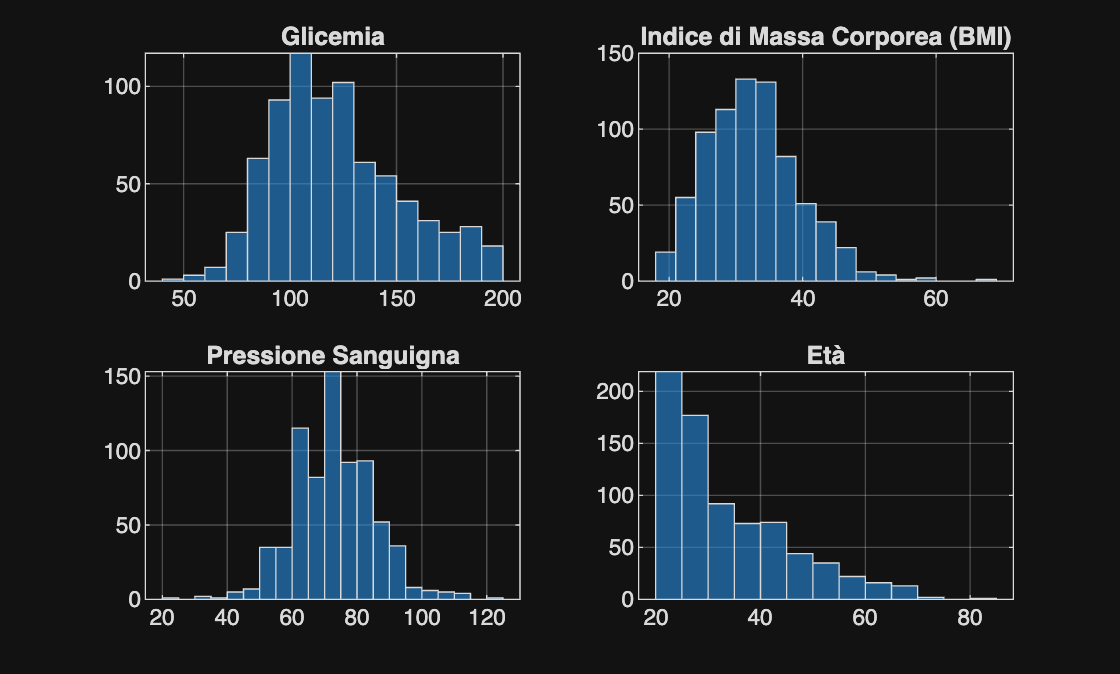

%  4 Visualizzazione delle distribuzioni

% visualizziamo la distribuzione delle variabili
% più importanti per capirne la forma e la scala. Creiamo degli istogrammi
% per le variabili chiave 

% Figure mi predispone una finestra per i grafici
figure; 
title( 'Distribuzione delle variabili Mediche Chiave');

% utilizziamo subplot(n,m,x), dove nxm mi da il numero di grafici all'interno della 
% figura, in questo modo possiamo ottenere più grafifi all'intenro della stessa figura 

% Grafico 1: Glicemia
subplot(2,2,1)
histogram(data_pulita.Glucose, 'BinMethod','auto');
title('Glicemia');
grid on;

% Grafico 2: Indice di Massa Corporea (BMI)
subplot(2,2,2)
histogram(data_pulita.BMI, 'BinMethod', 'auto');
title('Indice di Massa Corporea (BMI)');
grid on;

% Grafico 3: Pressione Sanguigna
subplot(2,2,3)
histogram(data_pulita.BloodPressure, 'BinMethod', 'auto');
title('Pressione Sanguigna');
grid on;

% Grafico 4: Età
subplot(2,2,4)
histogram(data_pulita.Age, 'BinMethod', 'auto');
title('Età');
grid on;

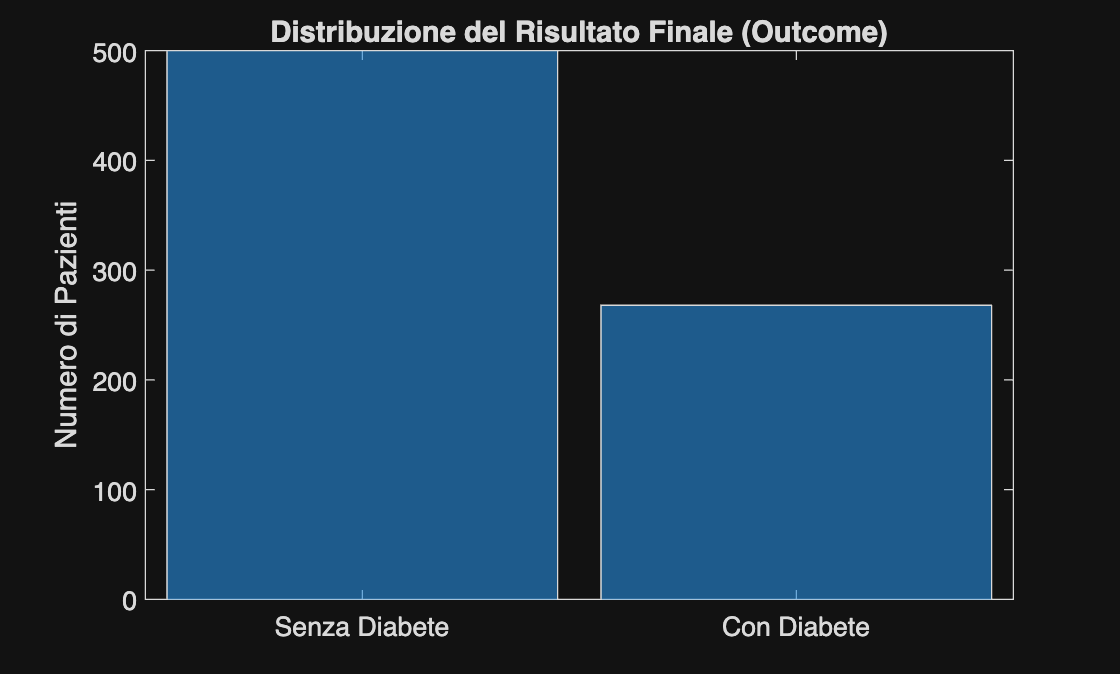

% 5 Analisi delle Variabili Target

% andiamo a controllare il bilanciamento della nostra vaiabile di oputput,
% 'Outcome' per capire quanti pazienti appartengono a ciascuna categoria (
% con Diabete e senza Diabete)

figure;
% etichettiamo i valori 0 e 1 in etichette categoriche per una migliore leggibilità.
C = categorical(data_pulita.Outcome, [0 1], {'Senza Diabete', 'Con Diabete'});
histogram(C);
title('Distribuzione del Risultato Finale (Outcome)');
ylabel('Numero di Pazienti');

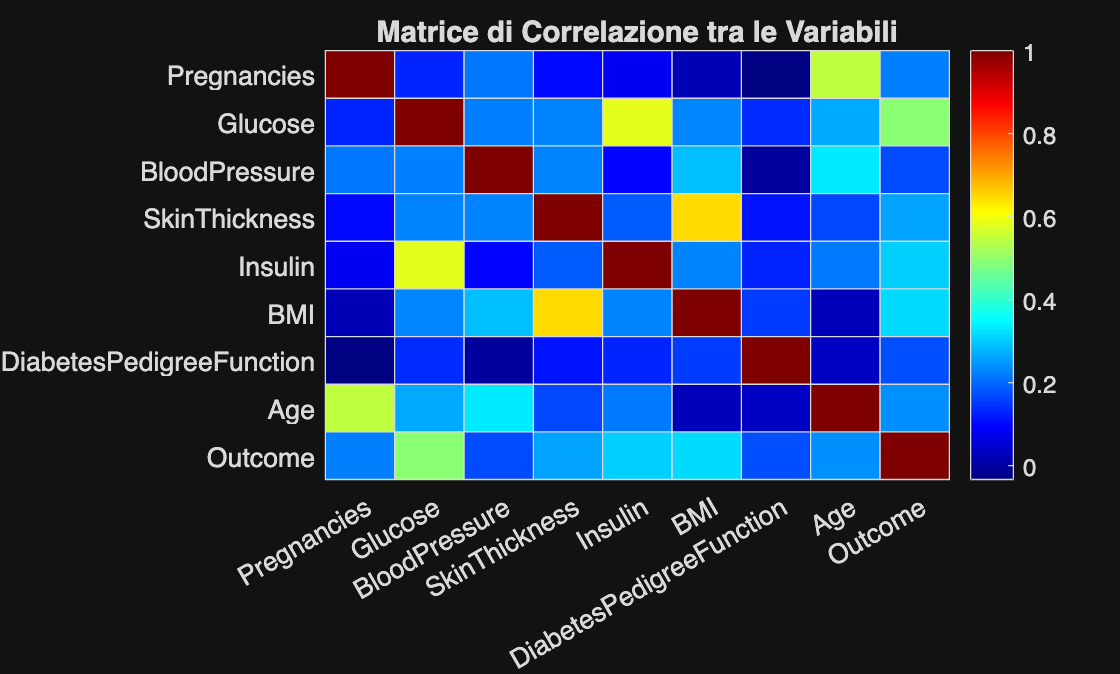

% 6. Matrice di Correlazione
figure;
% La funzione corrcoef richiede una matrice, quindi convertiamo la tabella.
% 'Rows','pairwise' permette di gestire i valori NaN correttamente durante il calcolo.
corr_matrix = corrcoef(table2array(data_pulita), 'Rows', 'pairwise');

% Prendiamo i nomi delle colonne per le etichette del grafico.
labels = data_pulita.Properties.VariableNames;

% Creiamo la heatmap.
heatmap(labels, labels, corr_matrix, 'Colormap', jet);
title('Matrice di Correlazione tra le Variabili');

% 7. Sostituzione con la Mediana

% sostituiamo i valori NaN con ma mediana di ogni colonna, 

% Inizializziamo la nuova tabella partendo da quella pulita.
data_imputata = data_pulita;

% Definiamo le colonne su cui abbiamo precedentemente inserito i NaN.
colonne_da_imputare = {'Glucose', 'BloodPressure', 'SkinThickness', 'Insulin', 'BMI'};

% Usiamo un ciclo per calcolare la mediana di ogni colonna e riempire i NaN.
for i = 1:length(colonne_da_imputare)

    % in nome_colonna vado a memorizzare il nome della colonna quindi
    % conterrà un char
    nome_colonna = colonne_da_imputare{i};
    
    % 1. Calcola la mediana di quella colonna, ignorando i valori NaN esistenti.
    mediana_colonna = median(data_imputata.(nome_colonna), 'omitnan');
    
    % 2. Trova gli indici dei valori NaN in quella colonna.
    indici_nan = isnan(data_imputata.(nome_colonna));
    
    % 3. Sostituisci i NaN con la mediana calcolata.
    data_imputata.(nome_colonna)(indici_nan) = mediana_colonna;
end

% Verifichiamo che non ci siano più valori mancanti.
disp('Riassunto statistico dopo l''imputazione con la mediana:');

Riassunto statistico dopo l'imputazione con la mediana:


summary(data_imputata);


data_imputata: 768×9 table

Variables:

    Pregnancies: double
    Glucose: double
    BloodPressure: double
    SkinThickness: double
    Insulin: double
    BMI: double
    DiabetesPedigreeFunction: double
    Age: double
    Outcome: double

Statistics for applicable variables:

                                NumMissing        Min          Median           Max            Mean            Std    

    Pregnancies                     0                 0              3             17          3.8451         3.3696  
    Glucose                         0                44            117            199        121.6562        30.4383  
    BloodPressure                 

% 8. Separazione delle Features (X) e del Target (Y)

% ora separiamo la tabella in due parti:
% 1. X(Features): le variabili di input che il modello userà per imparare
%    (Glicemia, BMI, Eta, etc..)
% 2. Y(Target): La variabile di output che vogliamo predire (la colonna outcome) 

% Le features sono tutte le colonne della nostra tabella imputata tranne l'ultima.
X = data_imputata(:, 1:end-1); 

% Il target è solo l'ultima colonna, 'Outcome'.
Y = data_imputata.Outcome;



% 9. Suddivisione del DataSet in training e Test Set

% Divideremo adesso i dati X e Y in un set di addestramento ( per insegnare al modello) 
% e un set di test ( per valutarne le performance su dati nuovi). 
% noi useremo cvpartition  

% Impostiamo un "seed" casuale per garantire che la suddivisione sia sempre
% la stessa ogni volta che eseguiamo lo script. È l'equivalente di 'random_state'.
rng(0); 

% Creiamo una partizione dei dati: 80% per il training, 20% per il test.
cv = cvpartition(height(data_imputata), 'HoldOut', 0.20);

% Usiamo gli indici generati dalla partizione per creare i nostri set di dati.
idx_train = training(cv);
idx_test = test(cv); 

X_train = X(idx_train, :);
Y_train = Y(idx_train, :);
X_test = X(idx_test, :);
Y_test = Y(idx_test, :);

disp(['Numero di campioni nel Training Set: ', num2str(height(X_train))]);

Numero di campioni nel Training Set: 615


disp(['Numero di campioni nel Test Set: ', num2str(height(X_test))]);

Numero di campioni nel Test Set: 153


% 10. Addestramento del Modello di Machine Learning K-NN

% il funzionamento del K-NN è molto intuitivo. Immaginiamo di dover capire
% se una nuova persona è a rischio diabete:
% 1. il modello cerca nel dataset di addestramento i K pazienti che sono
%    più simili a quello nuovo, basandosi sulle loro caratteristiche
%    (glicemia, BMI, età, etc.)
% 2. guarda l'esito di questi k vicini. Se la maggioranza di loro ha il
%    diabete, il modello predice che anche il nuovo paziente avrà il diabete.
%    altrimenti predice di no

% 'fitcknn' è la funzione di MATLAB per addestrare un classificatore k-Nearest Neighbors.
% Gli diamo in pasto i nostri dati di addestramento (X_train, Y_train).
% 'NumNeighbors' è il parametro 'k'. 
k = 11; 

% come interpretare il parmetro k: 
%   - valori bassi (3,5,7) modello molto specifico e sensibile ai dati
%     vicini
%   - valori medi ( 11-19) si trova il miglior compromesso
%   - valori alti (21-29) diventa più stabile ma rischia di essere troppo
%     generico 

%utilizziamo la 
knn_model = fitcknn(X_train, Y_train, 'NumNeighbors', k);

disp(['Modello k-NN (con k=', num2str(k), ') addestrato con successo!']);

Modello k-NN (con k=11) addestrato con successo!


% 11. Esecuzione delle Predizioni sul Test Set

% Usiamo la funzione 'predict' sul modello addestrato, passandogli
% le features del nostro test set (X_test).
Y_pred = predict(knn_model, X_test);

disp('Predizioni generate con successo sul test set.');

Predizioni generate con successo sul test set.


% 12. Calcolo dell'Accuratezza del Modello

% l'accuratezza è la metrica più semplice: ci dice la percentuale di
% previsioni corrette sul totale

% Confrontiamo le predizioni (Y_pred) con i valori reali (Y_test).
% 'sum(Y_pred == Y_test)' conta tutte le volte che la predizione è corretta.
% Dividiamo per il numero totale di campioni nel test set per ottenere la percentuale.
accuracy = sum(Y_pred == Y_test) / numel(Y_test);
%tot=0;
%for i= 1: length(Y_pred)
%    if Y_pred(i) == Y_test(i)
%        tot=tot+1;
%    end
%end
%accuratezza=tot/length(Y_test);

% Mostriamo il risultato in un formato leggibile.
disp(['Accuratezza del modello k-NN: ', num2str(accuracy * 100, '%.2f'), '%']);

Accuratezza del modello k-NN: 77.12%


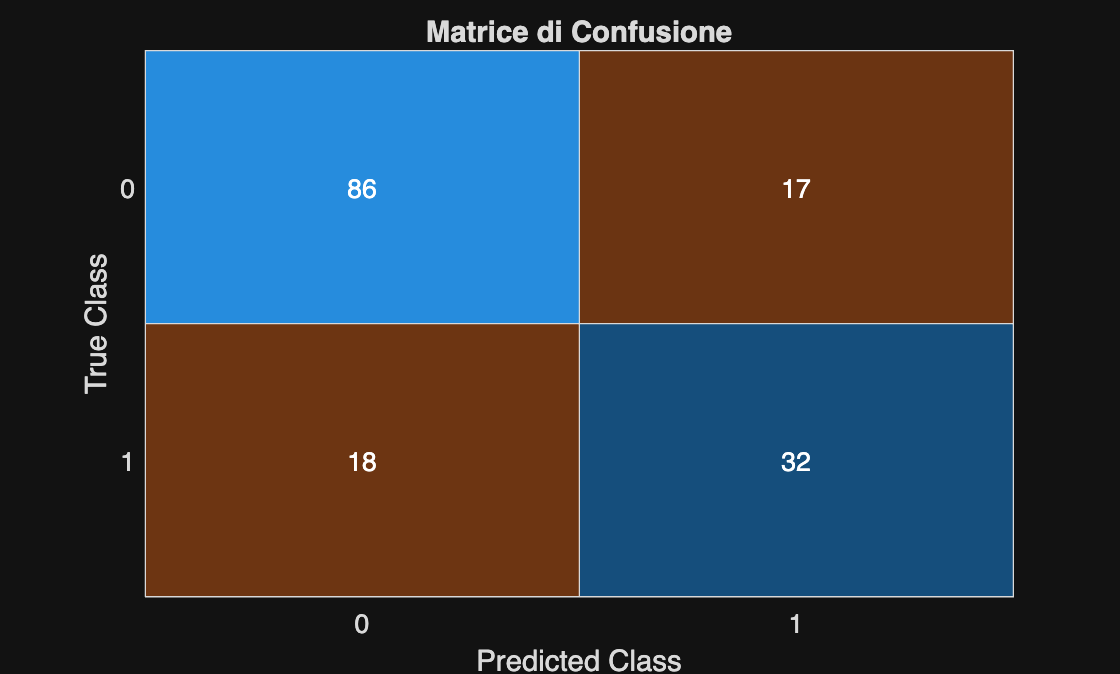

% 13. Visualizzazione della Matrice di Confusione (Versione Semplificata)

% la matrice di confusione è uno strumento molto più potente
% dell'accuratezza, perchè ci mostra dove il modello ha fatto bene e dove
% ha sbagliato. Ci mostra:
% - Veri positivi  (VP)
% - Veri Negativi  (VN)
% - Falsi Positivi (FP)
% - Falsi Negativi (FN) 

figure;
% Creiamo la matrice di confusione nella sua forma più semplice,
% senza alcuna opzione aggiuntiva. Questo ci aiuterà a isolare il problema.
confusionchart(Y_test, Y_pred);

title('Matrice di Confusione'); % Aggiungiamo un titolo semplice al grafico

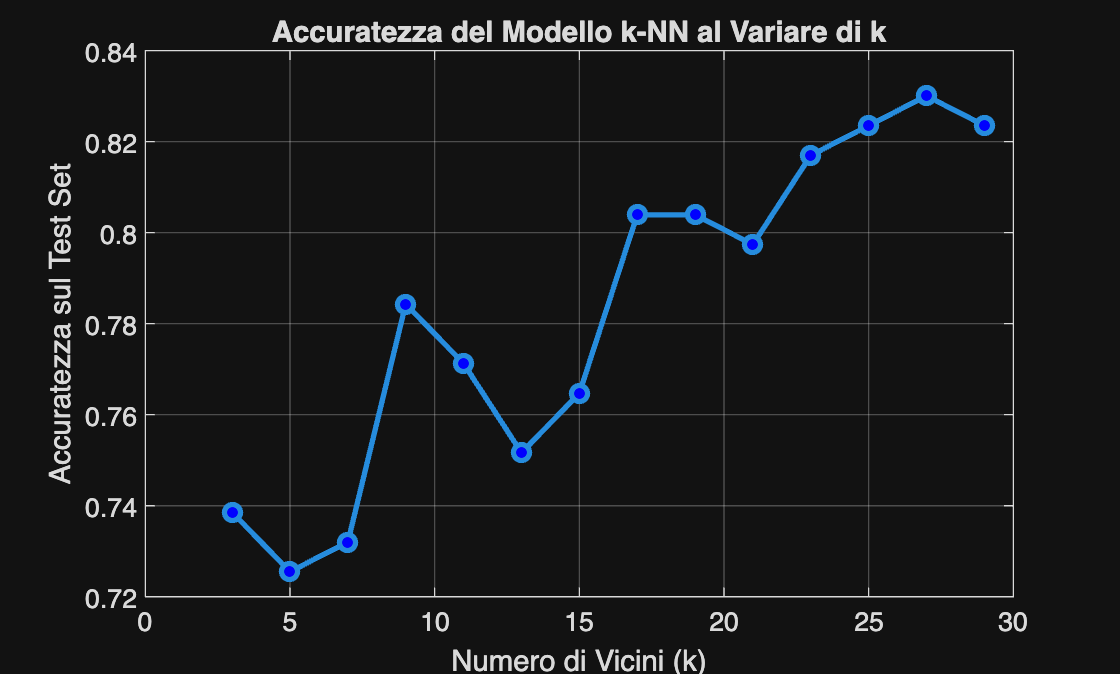

%% 13-bis. Ottimizzazione: Ricerca del k Ottimale

% Definiamo l'intervallo di k da testare (numeri dispari da 3 a 29)
k_values = 3:2:29;
accuracies = zeros(length(k_values), 1); % Vettore per salvare le accuratezze

% Ciclo per testare ogni valore di k
for i = 1:length(k_values)
    k = k_values(i);
    
    % Addestra il modello con il k corrente
    temp_model = fitcknn(X_train, Y_train, 'NumNeighbors', k);
    
    % Esegui le predizioni sul test set
    temp_pred = predict(temp_model, X_test);
    
    % Calcola e salva l'accuratezza
    accuracies(i) = sum(temp_pred == Y_test) / numel(Y_test);
end

% Creiamo un grafico per visualizzare i risultati
figure;
plot(k_values, accuracies, '-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
title('Accuratezza del Modello k-NN al Variare di k');
xlabel('Numero di Vicini (k)');
ylabel('Accuratezza sul Test Set');
grid on;


% Trova e stampa il k migliore
[max_accuracy, max_index] = max(accuracies);
best_k = k_values(max_index);

disp(['Ricerca del k ottimale completata.']);

Ricerca del k ottimale completata.


disp(['Il valore di k migliore è: ', num2str(best_k)]);

Il valore di k migliore è: 27


disp(['Accuratezza massima raggiunta: ', num2str(max_accuracy * 100, '%.2f'), '%']);

Accuratezza massima raggiunta: 83.01%



Glicemia =120; BMI = 25; Eta = 40; 

% 14. Esecuzione con un paziente virtuale 

% Creiamo un "paziente virtuale" con i valori medi del training set.


% prendo le medie delle features
medie_features = mean(table2array(X_train));
% prendo i nomi delle features
nomi_features = X_train.Properties.VariableNames;
% creo il mio paziente virtuale convertendo l'array in una tabella 
paziente_virtuale = array2table(medie_features, 'VariableNames', nomi_features);

% Aggiorniamo il paziente con i valori letti dagli slider.
paziente_virtuale.Glucose = Glicemia;
paziente_virtuale.BMI = BMI;
paziente_virtuale.Age = Eta;


% Usiamo il nostro modello addestrato per fare la predizione.
predizione = predict(knn_model, paziente_virtuale);

% Mostriamo il risultato all'utente in modo chiaro.
if predizione == 1
    disp('RISULTATO PREDIZIONE: Rischio Diabete (Classe 1)');
else
    disp('RISULTATO PREDIZIONE: Basso Rischio (Classe 0)');
end

RISULTATO PREDIZIONE: Rischio Diabete (Classe 1)


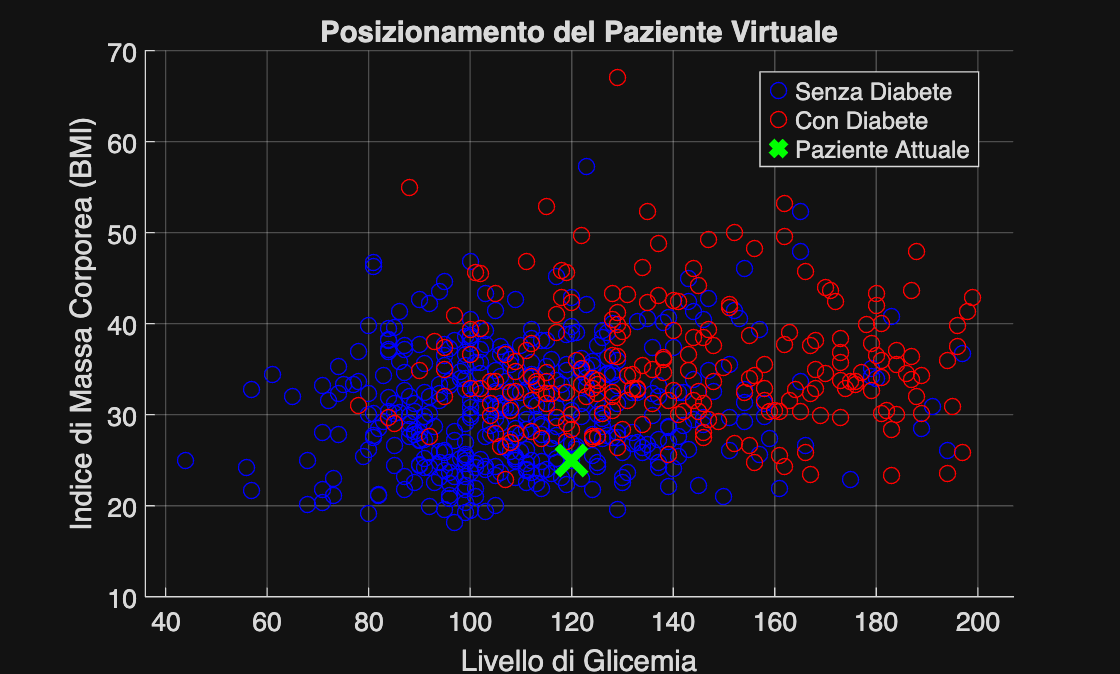


figure; % Crea una nuova finestra per il grafico per non sovrascrivere i precedenti
hold on; % Permette di disegnare più elementi sullo stesso grafico

% Disegniamo i punti del nostro training set, colorati in base all'outcome
gscatter(X_train.Glucose, X_train.BMI, Y_train, 'br', 'o'); % Blu per sani, Rosso per malati

% Ora, disegniamo il nostro paziente virtuale con un simbolo grande e diverso
plot(paziente_virtuale.Glucose, paziente_virtuale.BMI, 'gx', 'MarkerSize', 15, 'LineWidth', 3);

% Aggiungiamo etichette e una legenda per rendere il grafico comprensibile
title('Posizionamento del Paziente Virtuale');
xlabel('Livello di Glicemia');
ylabel('Indice di Massa Corporea (BMI)');
legend('Senza Diabete', 'Con Diabete', 'Paziente Attuale');
grid on;
hold off;

%% 15. Progettazione e Connessione al Database 


% --- Passo 1: Progettazione e Scelta del Database ---
%
% L'obiettivo è salvare i dati dei pazienti e i risultati delle predizioni.
% Per un'applicazione leggera come la nostra, la scelta ideale è un database
% file-based come SQLite, che non richiede un server e salva tutto in un unico file.
%   

% --- Passo 2: Connessione al Database da MATLAB ---
%
% Per connettersi a un database, MATLAB necessita di due componenti:
% 1. Il 'Database Toolbox': un componente aggiuntivo di MATLAB.
% 2. Un driver 'JDBC': un file che agisce da "traduttore" tra MATLAB e SQLite.
%
% Una volta configurati, il codice per creare e connettersi al file di database
% (es. 'progetto_diabete.db') sarebbe il seguente.
%{
    % Il file .db conterrebbe il nostro intero database
    dbfile = 'progetto_diabete.db'; 
    
    % La funzione 'database' crea la connessione usando il driver specificato
    conn = database(dbfile, '', '', 'org.sqlite.JDBC', ['jdbc:sqlite:', dbfile]);

comando fetch si usa per leggere o estrarre dati
comando exec si usa per effettuare delle azioni dul db esempio scrivere o
modificare dati

%}

%% 15. Creazione dello Schema del Database (4 Tabelle Normalizzato)

dbfile = 'progetto_diabete.db';

if exist(dbfile, 'file')
    conn = sqlite(dbfile, 'connect');
else
    conn = sqlite(dbfile, 'create');
end

% Tabella 1: Pazienti (Anagrafica)
create_pazienti_sql = ['CREATE TABLE IF NOT EXISTS Pazienti (' ...
                      'ID_Paziente INTEGER PRIMARY KEY AUTOINCREMENT, ' ...
                      'Codice_Fiscale TEXT UNIQUE NOT NULL, '...
                      'Nome TEXT, Cognome TEXT, Eta INT);'];
exec(conn, create_pazienti_sql);

% Tabella 2: VisiteMediche (Dati Clinici)
create_visite_sql = ['CREATE TABLE IF NOT EXISTS VisiteMediche (' ...
                     'ID_Visita INTEGER PRIMARY KEY AUTOINCREMENT, ' ...
                     'ID_Paziente INTEGER, ' ...
                     'Data_Visita TEXT, Pregnancies INT, Glucose INT, BloodPressure INT, ' ...
                     'SkinThickness INT, Insulin INT, BMI REAL, DiabetesPedigreeFunction REAL, ' ...
                     'FOREIGN KEY (ID_Paziente) REFERENCES Pazienti (ID_Paziente));'];
exec(conn, create_visite_sql);

% Tabella 3: TipiEsito (Lookup Table)
create_esiti_sql = ['CREATE TABLE IF NOT EXISTS TipiEsito (' ...
                    'ID_Esito INTEGER PRIMARY KEY, ' ...
                    'Descrizione TEXT);'];
exec(conn, create_esiti_sql);

% Popoliamo la tabella TipiEsito una sola volta
exec(conn, "INSERT OR IGNORE INTO TipiEsito (ID_Esito, Descrizione) VALUES (0, 'Basso Rischio')");
exec(conn, "INSERT OR IGNORE INTO TipiEsito (ID_Esito, Descrizione) VALUES (1, 'Rischio Diabete')");

% Tabella 4: Predizioni (Registro storico)
create_predizioni_sql = ['CREATE TABLE IF NOT EXISTS Predizioni (' ...
                         'ID_Predizione INTEGER PRIMARY KEY AUTOINCREMENT, ' ...
                         'ID_Visita INTEGER, ' ...
                         'ID_Esito INTEGER, ' ...
                         'FOREIGN KEY (ID_Visita) REFERENCES VisiteMediche (ID_Visita), '...
                         'FOREIGN KEY (ID_Esito) REFERENCES TipiEsito (ID_Esito));'];
exec(conn, create_predizioni_sql);

close(conn);
disp('Schema del database a 4 tabelle (normalizzato) creato/verificato.');

Schema del database a 4 tabelle (normalizzato) creato/verificato.


Nome="Marco"; Cognome="Polo"; CodiceFiscale="666"; Age=60;  

% inseriamo il paziente 
if CodiceFiscale == ""
    disp('ERRORE: Il Codice Fiscale è un campo obbligatorio. Inserimento annullato.');
else
   

    
    % 1. Connettiti al database
    dbfile = 'progetto_diabete.db';
    conn = sqlite(dbfile, 'connect');
    
    % 2. Gestisci il Paziente (Controlla se esiste, poi inserisci o aggiorna)
    select_paziente_sql = sprintf("SELECT ID_Paziente FROM Pazienti WHERE Codice_Fiscale = '%s'", CodiceFiscale);
    record_paziente = fetch(conn, select_paziente_sql);
    
    if ~isempty(record_paziente.ID_Paziente)
        % Se il paziente esiste, aggiorna
        id_paziente = record_paziente.ID_Paziente;
        update_paziente_sql = sprintf("UPDATE Pazienti SET Nome = '%s', Cognome = '%s', Eta = %d WHERE ID_Paziente = %d", ...
                                      Nome, Cognome, Age, id_paziente);
        exec(conn, update_paziente_sql);
        % andiamo a vedere cosa succede nella nostra tabella pazienti 
        lista_pazienti_sql = "SELECT * FROM Pazienti";
        lista_pazienti=  fetch(conn, lista_pazienti_sql);
        disp('lista di pazienti nella nostra tabella ');
        disp(lista_pazienti);

    else
        % Se il paziente non esiste, inseriscilo
        insert_paziente_sql = sprintf("INSERT INTO Pazienti (Codice_Fiscale, Nome, Cognome, Eta) VALUES ('%s', '%s', '%s', %d)", ...
                                      CodiceFiscale, Nome, Cognome, Age);
        exec(conn, insert_paziente_sql);
        id_paziente_table = fetch(conn, 'SELECT last_insert_rowid()');
        id_paziente = id_paziente_table{1,1};

         % andiamo a vedere cosa succede nella nostra tabella pazienti 
        lista_pazienti_sql = "SELECT * FROM Pazienti";
        lista_pazienti=  fetch(conn, lista_pazienti_sql);
        disp('lista di pazienti nella nostra tabella ');
        disp(lista_pazienti);
    end
    close(conn);
end 

lista di pazienti nella nostra tabella 


    ID_Paziente    Codice_Fiscale      Nome      Cognome    Eta
    ___________    ______________    ________    _______    ___

         1            "cccc"         "prova1"    "cup4"     30 
         2            "htbbs"        "prova3"    "cup5"     60 
         3            "666"          "Marco"     "Polo"     60 



disp ('Inserire un codice fiscale di un paziente già caricato ');

Inserire un codice fiscale di un paziente già caricato 


    "RISULTATO per visita del paziente con CF "    "666"    ": Rischio Diabete"



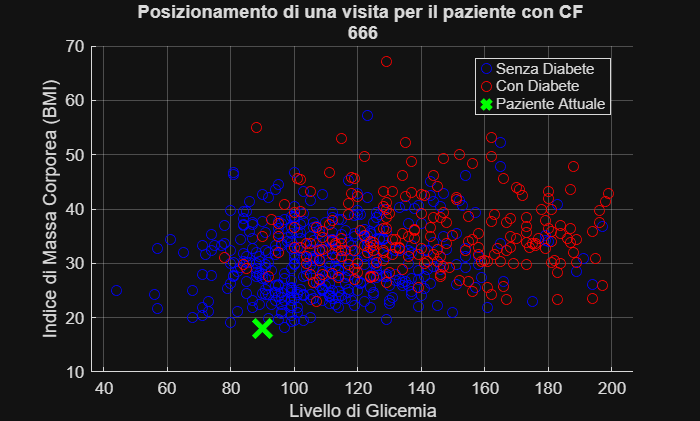


CodiceFiscaleVisita= "666";

Pregnancies=4; Glucose=90; BloodPressure=130;



SkinThickness=46; Insulin=270; BMI=18; 

Age=60;       

DiabetesPedigreeFunction=0.3725;
% connessione ad db
if CodiceFiscaleVisita == ""
    disp('Errore: inserire un codice fiscale valido')
else
    dbfile = 'progetto_diabete.db';
    conn = sqlite(dbfile, 'connect');

    % Verifica che il paziente esiste 
    select_paziente_sql = sprintf("SELECT ID_Paziente FROM Pazienti WHERE Codice_Fiscale = '%s'", CodiceFiscaleVisita);
    record_paziente = fetch(conn, select_paziente_sql);

    if isempty(record_paziente)
        disp(['ERRORE: Paziente con CF ', CodiceFiscaleVisita, ' non trovato. Inserire prima l''anagrafica.']);
        close(conn); % Chiudiamo la connessione se il paziente non c'è
    else
        % Se il paziente esiste, procediamo
        id_paziente = record_paziente.ID_Paziente;
        select_age = sprintf("SELECT Eta FROM Pazienti WHERE Codice_Fiscale = '%s'", CodiceFiscaleVisita);
        AgeVisita_risultato = fetch(conn,select_age);
        AgeVisita = AgeVisita_risultato.Eta;

        % 1. Raccogli i dati della visita e fai la predizione
        features = [Pregnancies, Glucose, BloodPressure, SkinThickness, Insulin, BMI, DiabetesPedigreeFunction, AgeVisita];
        nomi_features = X_train.Properties.VariableNames;
        visita_table = array2table(features, 'VariableNames', nomi_features);
        predizione = predict(knn_model, visita_table);

         % 2. Inserisci la Visita Medica
        insert_visita_sql = sprintf(['INSERT INTO VisiteMediche (ID_Paziente, Data_Visita, Pregnancies, Glucose, BloodPressure, SkinThickness, Insulin, BMI, DiabetesPedigreeFunction) '...
            'VALUES (%d, CURRENT_TIMESTAMP, %d, %d, %d, %d, %d, %.1f, %.3f)'], ...
        id_paziente, Pregnancies, Glucose, BloodPressure, SkinThickness, Insulin, BMI, DiabetesPedigreeFunction);
        exec(conn, insert_visita_sql);
        id_visita_table = fetch(conn, 'SELECT last_insert_rowid()');
        id_visita = id_visita_table{1,1};

        % 3. Inserisci la Predizione
        insert_pred_sql = sprintf("INSERT INTO Predizioni (ID_Visita, ID_Esito) VALUES (%d, %d)", id_visita, predizione);
        exec(conn, insert_pred_sql);
    
        close(conn); % Chiudiamo la connessione dopo aver finito
    
        % 4. Mostra il risultato e il grafico
        if predizione == 1
            disp(['RISULTATO per visita del paziente con CF ', CodiceFiscaleVisita, ': Rischio Diabete']);
        else
            disp(['RISULTATO per visita del paziente con CF ', CodiceFiscaleVisita, ': Basso Rischio']);
        end
    
        figure;
        hold on;
        gscatter(X_train.Glucose, X_train.BMI, Y_train, 'br', 'o');
        plot(visita_table.Glucose, visita_table.BMI, 'gx', 'MarkerSize', 15, 'LineWidth', 3);
        title(['Posizionamento di una visita per il paziente con CF ', CodiceFiscaleVisita]);
        xlabel('Livello di Glicemia');
        ylabel('Indice di Massa Corporea (BMI)');
        legend('Senza Diabete', 'Con Diabete', 'Paziente Attuale');
        grid on;
        hold off;
    end
end

% cercare Paziente 
disp('Inserisci un cognome da cercare ');

Inserisci un cognome da cercare 



CognomeDaCercare="Polo";  

%% 19. Logica di Ricerca 
% Si esegue quando si scrive un cognome e si preme sul tasto cerca.

dbfile = 'progetto_diabete.db';
conn = sqlite(dbfile, 'connect');

% COSTRUZIONE MANUALE DELLA QUERY 
% rispetto a prima adesso la query rislta più complessa infatti vanno fatti
% dei joi tra più tabelle per costruire il dato finale 
select_sql = sprintf(['SELECT p.Nome, p.Cognome, p.Codice_Fiscale, p.Eta, v.Data_Visita, v.Glucose, v.BMI, te.Descrizione AS Esito ' ...
                      'FROM Pazienti p ' ...
                      'JOIN VisiteMediche v ON p.ID_Paziente = v.ID_Paziente ' ...
                      'JOIN Predizioni pr ON v.ID_Visita = pr.ID_Visita ' ...
                      'JOIN TipiEsito te ON pr.ID_Esito = te.ID_Esito ' ...
                      'WHERE p.Cognome = ''%s'' ORDER BY v.Data_Visita DESC'], CognomeDaCercare);
                      
% Eseguiamo la 'fetch' con la query già completa, senza parametri aggiuntivi.
paziente_trovato = fetch(conn, select_sql);

close(conn);

% Controlliamo se la tabella restituita non è vuota
if ~isempty(paziente_trovato)
    disp(['Visite trovate per il cognome ''', CognomeDaCercare, ''':']);
    disp(paziente_trovato); % È già una tabella, la mostriamo direttamente
else
    disp(['Nessun paziente trovato con cognome ''', CognomeDaCercare, '''.']);
end

    "Visite trovate per il cognome '"    "Polo"    "':"



     Nome      Cognome    Codice_Fiscale    Eta         Data_Visita         Glucose    BMI          Esito      
    _______    _______    ______________    ___    _____________________    _______    ___    _________________

    "Marco"    "Polo"         "666"         60     "2025-09-03 16:43:10"      90       18     "Rischio Diabete"



disp('Scegli se visualizzare tutti i pazienti con basso rischio o alto rischio');

Scegli se visualizzare tutti i pazienti con basso rischio o alto rischio



outcome=1;


dbfile = 'progetto_diabete.db';
conn = sqlite(dbfile, 'connect');
% utilizziamo la stessa query utilizzata prima cambiando solo il where 
% Selezioniamo tutti i pazienti con l'esito scelto
%{
select_sql = sprintf("SELECT * FROM Pazienti WHERE Outcome_Predetto = %d", outcome);
pazienti_trovati = fetch(conn, select_sql);
close(conn);
%}

% COSTRUZIONE MANUALE DELLA QUERY 
select_sql = sprintf(['SELECT p.Nome, p.Cognome, p.Codice_Fiscale, p.Eta, v.Data_Visita, v.Glucose, v.BMI, te.Descrizione AS Esito ' ...
                      'FROM Pazienti p ' ...
                      'JOIN VisiteMediche v ON p.ID_Paziente = v.ID_Paziente ' ...
                      'JOIN Predizioni pr ON v.ID_Visita = pr.ID_Visita ' ...
                      'JOIN TipiEsito te ON pr.ID_Esito = te.ID_Esito ' ...
                      'WHERE pr.ID_Esito = ''%d'''], outcome);
                      
% Eseguiamo la 'fetch' con la query già completa, senza parametri aggiuntivi.
pazienti_trovati = fetch(conn, select_sql);

close(conn);

if ~isempty(pazienti_trovati)
    disp(['Pazienti trovati con esito "', num2str(outcome), '":']);
    disp((pazienti_trovati)); % Mostra tutti i risultati
else
    disp(['Nessun paziente trovato con esito "', num2str(outcome), '".']);
end

Pazienti trovati con esito "1":


      Nome      Cognome    Codice_Fiscale    Eta         Data_Visita         Glucose    BMI          Esito      
    ________    _______    ______________    ___    _____________________    _______    ___    _________________

    "prova3"    "cup5"        "htbbs"        60     "2025-09-03 16:42:09"      90       18     "Rischio Diabete"
    "Marco"     "Polo"        "666"          60     "2025-09-03 16:43:10"      90       18     "Rischio Diabete"



disp('inserisci il cognome da cambiare ');

inserisci il cognome da cambiare 



CognomeDaModificare="cup3"; NuovoCognome="cupnuovo";   

%% 21. Logica di Modifica Cognome (Automatica - Corretta)
% Si esegue quando si inserisce un valore nel campo 'NuovoCognome'.

dbfile = 'progetto_diabete.db';
conn = sqlite(dbfile, 'connect');

% Trova il paziente da modificare
select_id_sql = sprintf("SELECT ID_Paziente FROM Pazienti WHERE Cognome = '%s' LIMIT 1", CognomeDaModificare);
risultato_id_table = fetch(conn, select_id_sql);

if ~isempty(risultato_id_table)
    % ESTRAIAMO IL NUMERO DALLA TABELLA
    id_da_aggiornare = risultato_id_table.ID_Paziente;
    
    % Ora usiamo il numero 'id_da_aggiornare' in sprintf
    update_sql = sprintf("UPDATE Pazienti SET Cognome = '%s' WHERE ID_Paziente = %d", ...
                         NuovoCognome, id_da_aggiornare);
    exec(conn, update_sql);
    
    disp(['Paziente con ID ', num2str(id_da_aggiornare), ' aggiornato con successo.']);
else
    disp(['Nessun paziente trovato con il cognome ''', CognomeDaModificare, '''.']);
end

    "Nessun paziente trovato con il cognome '"    "cup3"    "'."



close(conn);
